syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[-0.142;-4.31;7.83];
u31=[0.221;0.975;0];
r2=[0.142;4.31;-7.94];
u32=[-0.221;-0.975;0];
r3=[15.31;4.31;-2.24];
u33=[0.221;0.975;0];
r4=[15.03;-4.31;-18.01];
u34=[-0.221;-0.975;0];
r5=[15.59;12.93;-18.01];
u35=[-0.221;-0.975;0];

% center and direction of spheroids

axis([5 15 5 15]);
for R3=6:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    hold on
    scatter(R1,R3,'b')
    xlabel('R1'); ylabel('R3');
end

ans =    11.1500    6.0000    1.0032


ans =    10.8000    6.2000    1.0049


ans =    10.5500    6.4000    1.0021


ans =    10.3000    6.6000    1.0038


ans =    10.1000    6.8000    1.0036


ans =     9.9500    7.0000    1.0005


ans =     9.8000    7.2000    1.0001


ans =     9.6500    7.4000    1.0022


ans =     9.5000    7.6000    1.0066


ans =     9.4000    7.8000    1.0058


ans =     9.3000    8.0000    1.0067


ans =     9.2500    8.2000    1.0011


ans =     9.1500    8.4000    1.0047


ans =     9.1000    8.6000    1.0013


ans =     9.0000    8.8000    1.0073


ans =     8.9500    9.0000    1.0058


ans =     8.9000    9.2000    1.0052


ans =     8.8500    9.4000    1.0052


ans =     8.8000    9.6000    1.0060


ans =     8.7500    9.8000    1.0075


ans =     8.7500   10.0000    1.0001


ans =     8.7000   10.2000    1.0026


ans =     8.6500   10.4000    1.0056


ans =     8.6000   10.6000    1.0092


ans =     8.6000   10.8000    1.0034


ans =     8.5500   11.0000    1.0078


ans =     8.5500   11.2000    1.0026


ans =     8.5000   11.4000    1.0077


ans =     8.5000   11.6000    1.0030


ans =     8.4500   11.8000    1.0089


ans =     8.4500   12.0000    1.0046


ans =     8.4500   12.2000    1.0006


ans =     8.4000   12.4000    1.0072


ans =     8.4000   12.6000    1.0035


ans =     8.4000   12.8000    1.0000


ans =     8.3500   13.0000    1.0074


ans =     8.3500   13.2000    1.0042


ans =     8.3500   13.4000    1.0012


ans =     8.3000   13.6000    1.0091


ans =     8.3000   13.8000    1.0064


ans =     8.3000   14.0000    1.0037


ans =     8.3000   14.2000    1.0011


ans =     8.2500   14.4000    1.0098


ans =     8.2500   14.6000    1.0074


ans =     8.2500   14.8000    1.0051


ans =     8.2500   15.0000    1.0030




for R3=7:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'r')
    xlabel('R1'); ylabel('R3');
end

ans =     8.1500    7.0000    1.0032


ans =     8.1500    7.2000    1.0001


ans =     8.1000    7.4000    1.0089


ans =     8.1000    7.6000    1.0063


ans = 1×3
    8.1000    7.8000    1.0038


ans = 1×3
    8.1000    8.0000    1.0015


ans = 1×3
    8.0500    8.2000    1.0113


ans = 1×3
    8.0500    8.4000    1.0094


ans = 1×3
    8.0500    8.6000    1.0075


ans = 1×3
    8.0500    8.8000    1.0058


ans = 1×3
    8.0500    9.0000    1.0042


ans = 1×3
    8.0500    9.2000    1.0028


ans = 1×3
    8.0500    9.4000    1.0014


ans = 1×3
    8.0500    9.6000    1.0000


ans = 1×3
    8.0000    9.8000    1.0110


ans = 1×3
    8.0000   10.0000    1.0098


ans = 1×3
    8.0000   10.2000    1.0087


ans = 1×3
    8.0000   10.4000    1.0077


ans = 1×3
    8.0000   10.6000    1.0067


ans = 1×3
    8.0000   10.8000    1.0058


ans = 1×3
    8.0000   11.0000    1.0049


ans = 1×3
    8.0000   11.2000    1.0041


ans = 1×3
    8.0000   11.4000    1.0033


ans = 1×3
    8.0000   11.6000    1.0026


ans = 1×3
    8.0000   11.8000    1.0019


ans = 1×3
    8.0000   12.0000    1.0012


ans = 1×3
    8.0000   12.2000    1.0006


ans = 1×3
    7.9500   12.4000    1.0124


ans = 1×3
    7.9500   12.6000    1.0118


ans = 1×3
    7.9500   12.8000    1.0113


ans = 1×3
    7.9500   13.0000    1.0107


ans = 1×3
    7.9500   13.2000    1.0102


ans = 1×3
    7.9500   13.4000    1.0098


ans = 1×3
    7.9500   13.6000    1.0093


ans = 1×3
    7.9500   13.8000    1.0089


ans = 1×3
    7.9500   14.0000    1.0084


ans = 1×3
    7.9500   14.2000    1.0080


ans = 1×3
    7.9500   14.4000    1.0077


ans = 1×3
    7.9500   14.6000    1.0073


ans = 1×3
    7.9500   14.8000    1.0069


ans = 1×3
    7.9500   15.0000    1.0066



for R3=7:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'cyan')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
   10.3000    7.0000    1.0082


ans = 1×3
   10.3000    7.2000    1.0009


ans = 1×3
   10.2500    7.4000    1.0027


ans = 1×3
   10.2000    7.6000    1.0052


ans = 1×3
   10.1500    7.8000    1.0083


ans = 1×3
   10.1500    8.0000    1.0030


ans = 1×3
   10.1000    8.2000    1.0070


ans = 1×3
   10.1000    8.4000    1.0024


ans = 1×3
   10.0500    8.6000    1.0072


ans = 1×3
   10.0500    8.8000    1.0032


ans = 1×3
   10.0000    9.0000    1.0087


ans = 1×3
   10.0000    9.2000    1.0053


ans = 1×3
   10.0000    9.4000    1.0020


ans = 1×3
    9.9500    9.6000    1.0083


ans = 1×3
    9.9500    9.8000    1.0055


ans = 1×3
    9.9500   10.0000    1.0028


ans = 1×3
    9.9500   10.2000    1.0002


ans = 1×3
    9.9000   10.4000    1.0073


ans = 1×3
    9.9000   10.6000    1.0051


ans = 1×3
    9.9000   10.8000    1.0029


ans = 1×3
    9.9000   11.0000    1.0009


ans = 1×3
    9.8500   11.2000    1.0086


ans = 1×3
    9.8500   11.4000    1.0068


ans = 1×3
    9.8500   11.6000    1.0051


ans = 1×3
    9.8500   11.8000    1.0035


ans = 1×3
    9.8500   12.0000    1.0019


ans = 1×3
    9.8500   12.2000    1.0004


ans = 1×3
    9.8000   12.4000    1.0088


ans = 1×3
    9.8000   12.6000    1.0075


ans = 1×3
    9.8000   12.8000    1.0062


ans = 1×3
    9.8000   13.0000    1.0050


ans = 1×3
    9.8000   13.2000    1.0038


ans = 1×3
    9.8000   13.4000    1.0027


ans = 1×3
    9.8000   13.6000    1.0016


ans = 1×3
    9.8000   13.8000    1.0006


ans = 1×3
    9.7500   14.0000    1.0096


ans = 1×3
    9.7500   14.2000    1.0086


ans = 1×3
    9.7500   14.4000    1.0077


ans = 1×3
    9.7500   14.6000    1.0069


ans = 1×3
    9.7500   14.8000    1.0061


ans = 1×3
    9.7500   15.0000    1.0053



for R3=7:0.2:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'magenta')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
   15.4000    7.0000    1.0016


ans = 1×3
   14.4500    7.2000    1.0021


ans = 1×3
   13.7500    7.4000    1.0006


ans = 1×3
   13.1500    7.6000    1.0014


ans = 1×3
   12.6500    7.8000    1.0029


ans = 1×3
   12.2500    8.0000    1.0031


ans = 1×3
   11.9500    8.2000    1.0001


ans = 1×3
   11.6500    8.4000    1.0008


ans = 1×3
   11.4000    8.6000    1.0005


ans = 1×3
   11.1500    8.8000    1.0032


ans = 1×3
   10.9500    9.0000    1.0038


ans = 1×3
   10.8000    9.2000    1.0013


ans = 1×3
   10.6500    9.4000    1.0006


ans = 1×3
   10.5000    9.6000    1.0017


ans = 1×3
   10.3500    9.8000    1.0046


ans = 1×3
   10.2500   10.0000    1.0028


ans = 1×3
   10.1500   10.2000    1.0022


ans = 1×3
   10.0500   10.4000    1.0027


ans = 1×3
    9.9500   10.6000    1.0044


ans = 1×3
    9.8500   10.8000    1.0071


ans = 1×3
    9.8000   11.0000    1.0036


ans = 1×3
    9.7500   11.2000    1.0007


ans = 1×3
    9.6500   11.4000    1.0061


ans = 1×3
    9.6000   11.6000    1.0046


ans = 1×3
    9.5500   11.8000    1.0037


ans = 1×3
    9.5000   12.0000    1.0033


ans = 1×3
    9.4500   12.2000    1.0035


ans = 1×3
    9.4000   12.4000    1.0042


ans = 1×3
    9.3500   12.6000    1.0054


ans = 1×3
    9.3000   12.8000    1.0071


ans = 1×3
    9.3000   13.0000    1.0005


ans = 1×3
    9.2500   13.2000    1.0029


ans = 1×3
    9.2000   13.4000    1.0057


ans = 1×3
    9.2000   13.6000    1.0001


ans = 1×3
    9.1500   13.8000    1.0035


ans = 1×3
    9.1000   14.0000    1.0073


ans = 1×3
    9.1000   14.2000    1.0024


ans = 1×3
    9.0500   14.4000    1.0068


ans = 1×3
    9.0500   14.6000    1.0022


ans = 1×3
    9.0000   14.8000    1.0071


ans = 1×3
    9.0000   15.0000    1.0029



for R1=5:0.2:15 %离心率
    R3=8.5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r4,r5,R1,R3,u34,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r4,r5,R1,R3,u34,u35);
    end
    [R1,R3,miu2]

    scatter(R1,R3,'black')
    xlabel('R1'); ylabel('R3');
end

ans = 1×3
    5.0000    8.9500    1.0026


ans = 1×3
    5.2000    8.9000    1.0046


ans = 1×3
    5.4000    8.8500    1.0076


ans = 1×3
    5.6000    8.8500    1.0012


ans = 1×3
    5.8000    8.8000    1.0058


ans = 1×3
    6.0000    8.8000    1.0006


ans = 1×3
    6.2000    8.7500    1.0064


ans = 1×3
    6.4000    8.7500    1.0021


ans = 1×3
    6.6000    8.7000    1.0090


ans = 1×3
    6.8000    8.7000    1.0054


ans = 1×3
    7.0000    8.7000    1.0021


ans = 1×3
    7.2000    8.6500    1.0101


ans = 1×3
    7.4000    8.6500    1.0073


ans = 1×3
    7.6000    8.6500    1.0048


ans = 1×3
    7.8000    8.6500    1.0024


ans = 1×3
    8.0000    8.6500    1.0002


ans = 1×3
    8.2000    8.6000    1.0094


ans = 1×3
    8.4000    8.6000    1.0075


ans = 1×3
    8.6000    8.6000    1.0057


ans = 1×3
    8.8000    8.6000    1.0041


ans = 1×3
    9.0000    8.6000    1.0025


ans = 1×3
    9.2000    8.6000    1.0011


ans = 1×3
    9.4000    8.5500    1.0111


ans = 1×3
    9.6000    8.5500    1.0099


ans = 1×3
    9.8000    8.5500    1.0087


ans = 1×3
   10.0000    8.5500    1.0075


ans = 1×3
   10.2000    8.5500    1.0065


ans = 1×3
   10.4000    8.5500    1.0055


ans = 1×3
   10.6000    8.5500    1.0045


ans = 1×3
   10.8000    8.5500    1.0037


ans = 1×3
   11.0000    8.5500    1.0028


ans = 1×3
   11.2000    8.5500    1.0020


ans = 1×3
   11.4000    8.5500    1.0012


ans = 1×3
   11.6000    8.5500    1.0005


ans = 1×3
   11.8000    8.5000    1.0114


ans = 1×3
   12.0000    8.5000    1.0107


ans = 1×3
   12.2000    8.5000    1.0101


ans = 1×3
   12.4000    8.5000    1.0095


ans = 1×3
   12.6000    8.5000    1.0090


ans = 1×3
   12.8000    8.5000    1.0084


ans = 1×3
   13.0000    8.5000    1.0079


ans = 1×3
   13.2000    8.5000    1.0074


ans = 1×3
   13.4000    8.5000    1.0069


ans = 1×3
   13.6000    8.5000    1.0065


ans = 1×3
   13.8000    8.5000    1.0060


ans = 1×3
   14.0000    8.5000    1.0056


ans = 1×3
   14.2000    8.5000    1.0052


ans = 1×3
   14.4000    8.5000    1.0048


ans = 1×3
   14.6000    8.5000    1.0044


ans = 1×3
   14.8000    8.5000    1.0041


ans = 1×3
   15.0000    8.5000    1.0037


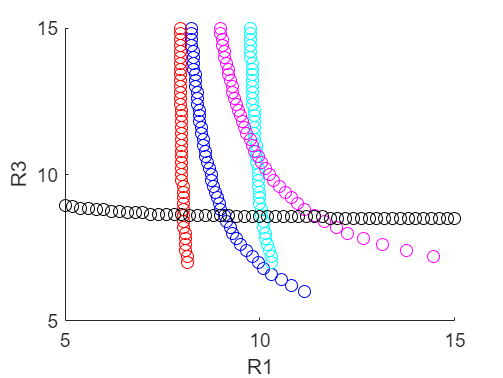

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

